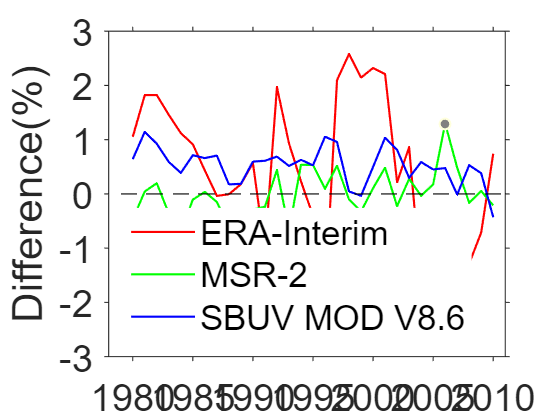

clear;clc;
load data1.mat

% 创建 figure
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);

% 创建 axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

% 使用 plot 的矩阵输入创建多行
plot1 = plot([MRD1',MRD2',MRD3'],'LineWidth',1);
set(plot1(1),'DisplayName','ERA-Interim','Color',[1 0 0]);
set(plot1(2),'DisplayName','MSR-2','Color',[0 1 0]);
set(plot1(3),'DisplayName','SBUV MOD V8.6','Color',[0 0 1]);

% 创建 ylabel
ylabel({'Difference(%)'},'FontName','Arial','FontSize',22);

% 添加参考线
line = refline(axes1,0,0);
set(line,'Color',[0 0 0],'LineStyle','--')
% 图例中不显示line
line.Annotation.LegendInformation.IconDisplayStyle = 'off';

% 设置坐标区范围
xlim([-1 32])
ylim([-3 3])

% 设置刻度和显示文字
yticks('manual')
xticks('manual')
yticks([-4:1:3])
xticks([1:5:31])
xticklabels('manual')
xticklabels([1980:5:2010])

% 设置xlabel水平
set(gca,'XTickLabelRotation',0);

box(axes1,'on');
hold(axes1,'off');
% 设置其余坐标区属性
set(gca,'FontName','Arial','FontSize',18);
% 创建 legend
legend1 = legend(axes1,'show');
set(legend1,'Location','southwest','EdgeColor','none');
% 刻度线朝外
set(gca,'tickdir','out')
% 保存图片
set(gcf,'paperpositionmode','auto');
print(figure1,'data1','-dpdf','-r300','-cmyk')

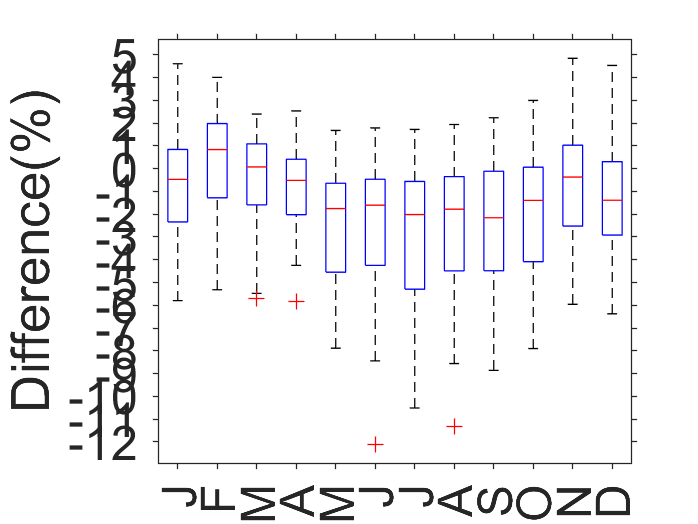

clear;clc;
load data2.mat
% 创建 figure
figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);

% 创建 axes
axes1 = axes('Parent',figure1);
boxplot(ERA1')

% 创建 ylabel
ylabel({'Difference(%)'},'FontName','Arial','FontSize',22);
yticks([-20:1:10])
% 设置刻度和显示文字
set(axes1,'XTick',...
    [1 2 3 4 5 6 7 8 9 10 11 12],'XTickLabel',...
    {'J','F','M','A','M','J','J','A','S','O','N','D'});
% 刻度线朝外
set(gca,'tickdir','out')
% 设置其余坐标区属性
set(gca,'FontName','Arial','FontSize',18);

set(gcf,'paperpositionmode','auto');
print(figure1,'data2','-depsc','-r300','-cmyk')